# Model Effect of Barrage Jammer on Target Echo

This example demonstrates how to simulate the effect of a barrage jammer on a target echo. First, create the required objects. You need an array, a transmitter, a radiator, a target, a jammer, a collector, and a receiver. Additionally, you need to define two propagation paths: one from the array to the target and back, and the other path from the jammer to the array.

antenna = phased.ULA(4); 
Fs = 1e6;
fc = 1e9;
rng("default")
waveform = phased.RectangularWaveform("PulseWidth",100e-6,...
    "PRF",1e3,"NumPulses",5,"SampleRate",Fs);
transmitter = phased.Transmitter("PeakPower",1e4,"Gain",20,...
    "InUseOutputPort",true);
radiator = phased.Radiator("Sensor",antenna,"OperatingFrequency",fc);
jammer = barrageJammer("ERP",1000,...
    "SamplesPerFrame",waveform.NumPulses*waveform.SampleRate/waveform.PRF);
target = phased.RadarTarget("Model","Nonfluctuating",...
    "MeanRCS",1,"OperatingFrequency",fc);
targetchannel = phased.FreeSpace("TwoWayPropagation",true,...
    "SampleRate",Fs,"OperatingFrequency", fc);
jammerchannel = phased.FreeSpace("TwoWayPropagation",false,...
    "SampleRate",Fs,"OperatingFrequency", fc);
collector = phased.Collector("Sensor",antenna,...
    "OperatingFrequency",fc);
amplifier = phased.Receiver("EnableInputPort",true);

Assume that the array, target, and jammer are stationary. The array is located at the global origin, *(0,0,0)*. The target is located at *(1000,500,0)*, and the jammer is located at *(2000,2000,100)*. Determine the directions from the array to the target and jammer.

targetloc = [1000 ; 500; 0];
jammerloc = [2000; 2000; 100];
[~,tgtang] = rangeangle(targetloc);
[~,jamang] = rangeangle(jammerloc);

Finally, transmit the rectangular pulse waveform to the target, reflect it off the target, and collect the echo at the array. Simultaneously, the jammer transmits a jamming signal toward the array. The jamming signal and echo are mixed at the receiver. Generate waveform

wav = waveform();
% Transmit waveform
[wav,txstatus] = transmitter(wav);
% Radiate pulse toward the target
wav = radiator(wav,tgtang);
% Propagate pulse toward the target
wav = targetchannel(wav,[0;0;0],targetloc,[0;0;0],[0;0;0]);
% Reflect it off the target
wav = target(wav);
% Collect the echo
wav = collector(wav,tgtang);

Generate the jamming signal

jamsig = jammer();
% Propagate the jamming signal to the array
jamsig = jammerchannel(jamsig,jammerloc,[0;0;0],[0;0;0],[0;0;0]);
% Collect the jamming signal
jamsig = collector(jamsig,jamang);

% Receive target echo alone and target echo + jamming signal
pulsewave = amplifier(wav,~txstatus);
pulsewave_jamsig = amplifier(wav + jamsig,~txstatus);

Plot the result, and compare it with received waveform with and without jamming.

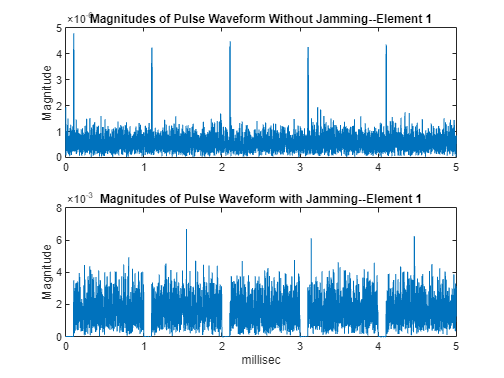

subplot(2,1,1)
t = unigrid(0,1/Fs,size(pulsewave,1)*1/Fs,"[)");
plot(t*1000,abs(pulsewave(:,1)))
title("Magnitudes of Pulse Waveform Without Jamming--Element 1")
ylabel("Magnitude")
subplot(2,1,2)
plot(t*1000,abs(pulsewave_jamsig(:,1)))
title("Magnitudes of Pulse Waveform with Jamming--Element 1")
xlabel("millisec")
ylabel("Magnitude")

*Copyright 2024 The MathWorks, Inc.*